# HARVEY'S IMPACT

## Background and Scope

[Hurricane Harvey](https://www.weather.gov/hgx/hurricaneharvey) had a great impact and resulted in a lot of damage cost to the country. Let's find out the most affected areas.

### Import the Data

Let us import dataset for the events held in 2017 and filter out the events with no data about property cost.

data = finalimport('StormEvents_2017_finalProject.csv');
data = data(~ismissing(data.Property_Cost),:)

data = 46415×24 table
    EpisodeID      Event_ID         State         Year     Month             Event_Type                                    CZ_Name                                Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                         

### Two States Most Impacted by Harvey

Now, since Harvey impacted only **Arkansas, Kentucky, Louisiana, Mississippi, North Carolina, Tennessee, and Texas**, we shall filter out the remaining states from the table, i.e., events irrelevant from Harvey. We shall further filter out the events which didn't occur during or the irrelevant data as the Harvey's events occured between 17th of August and 3rd of September. 

harvey_data = data(ismember(data.State,{'ARKANSAS','KENTUCKY','LOUISIANA','MISSISSIPPI','NORTH CAROLINA','TENNESSEE','TEXAS'}),:);
begindate = datetime("2017-08-17 00:00:00");
enddate = datetime("2017-09-03 23:59:59");

harvey_data = harvey_data(harvey_data.Begin_Date_Time >= begindate & harvey_data.End_Date_Time <= enddate, :);
harvey_data.Event_Type = removecats(harvey_data.Event_Type,{'Astronomical Low Tide','Avalanche','Blizzard','Coastal Flood','Cold/Wind Chill','Debris Flow','Dense Fog','Dense Smoke','Drought','Dust Devil','Dust Storm','Excessive Heat','Extreme Cold/Wind Chill','Freezing Fog','Frost/Freeze','Heavy Snow','High Surf','Ice Storm','Lake-Effect Snow','Lakeshore Flood','Marine Hail','Marine High Wind','Marine Hurricane/Typhoon','Marine Strong Wind','Marine Thunderstorm Wind','Marine Tropical Depression','Marine Tropical Storm','Rip Current','Sleet','Sneakerwave','Tropical Depression','Waterspout','Wildfire','Winter Storm','Winter Weather'})

harvey_data = 562×24 table
    EpisodeID      Event_ID         State         Year      Month         Event_Type          CZ_Name        Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                         

The total cost to property for every state during the Hurricane Harvey is listed below sorted in descending order of the cost. Since the Harvey was most prominent and destructive event during the time, it will be the reason for most cost to property damage, i.e., no other event during that time was more destructive than Harvey. 

total = groupsummary(harvey_data, 'State', 'sum', 'Property_Cost');
total = sortrows(total, 3, 'descend')

total = 7×3 table
        State         GroupCount    sum_Property_Cost
    ______________    __________    _________________

    TEXAS                270           7.7427e+10    
    LOUISIANA             85           7.5277e+07    
    NORTH CAROLINA        54           1.2339e+07    
    MISSISSIPPI           39             9.15e+05    
    TENNESSEE             46             5.04e+05    
    KENTUCKY              16             4.35e+05    
    ARKANSAS              52                61000    


Hence, it the top 2 in the below table are the 2 most impacted states in order.

total = total(1:2,1)

total = 2×1 table
      State  
    _________

    TEXAS    
    LOUISIANA


### Table of Events for Two Most Impacted States

A few rows of events that include only the two most affected states are shown below. 

harvey_top = harvey_data(harvey_data.State == "TEXAS" | harvey_data.State == "LOUISIANA", :);
harvey_top.State = removecats(harvey_top.State,{'ALABAMA','ALASKA','AMERICAN SAMOA','ARIZONA','ARKANSAS','ATLANTIC NORTH','ATLANTIC SOUTH','CALIFORNIA','COLORADO','CONNECTICUT','DELAWARE','DISTRICT OF COLUMBIA','E PACIFIC','FLORIDA','GEORGIA','GUAM','GULF OF MEXICO','HAWAII','HAWAII WATERS','IDAHO','ILLINOIS','INDIANA','IOWA','KANSAS','KENTUCKY','LAKE ERIE','LAKE HURON','LAKE MICHIGAN','LAKE ONTARIO','LAKE ST CLAIR','LAKE SUPERIOR','UTAH','VERMONT','VIRGIN ISLANDS','VIRGINIA','WASHINGTON','WEST VIRGINIA','WISCONSIN','WYOMING','MAINE','MARYLAND','MASSACHUSETTS','MICHIGAN','MINNESOTA','MISSISSIPPI','MISSOURI','MONTANA','NEBRASKA','NEVADA','NEW HAMPSHIRE','NEW JERSEY','NEW MEXICO','NEW YORK','NORTH CAROLINA','NORTH DAKOTA','OHIO','OKLAHOMA','OREGON','PENNSYLVANIA','PUERTO RICO','RHODE ISLAND','SOUTH CAROLINA','SOUTH DAKOTA','ST LAWRENCE R','TENNESSEE'});
harvey_top.Event_Type = removecats(harvey_top.Event_Type,{'High Wind','Lightning','Strong Wind'});
head(harvey_top, 15)

ans = 15×24 table
    EpisodeID      Event_ID     State    Year    Month        Event_Type          CZ_Name        Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                                              

## Visualizations

### Figure of Event Types

A figure showing the type and number of occurances for events related to Harvey in the two states is shown below. Events with zero occurences have already been removed from the dataset.

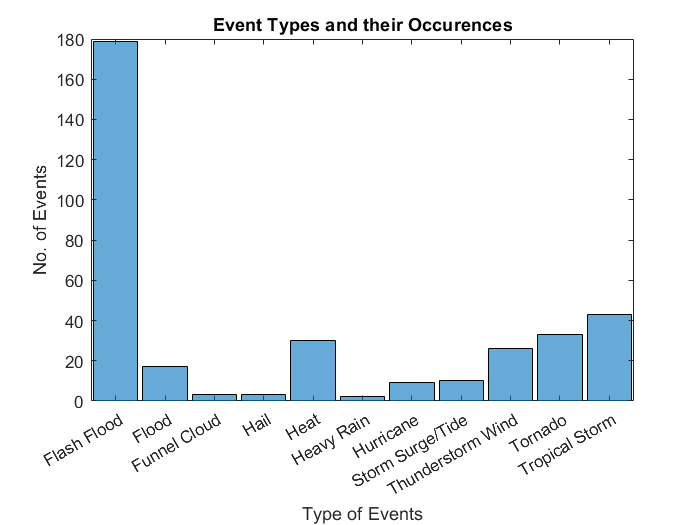

histogram(harvey_top.Event_Type)

title('Event Types and their Occurences')

xlabel('Type of Events')
ylabel('No. of Events')

### Figure of Event Locations

Below are the locations of events in the two states. The size of marker depends upon the property cost of the event.

#### Begin Locations

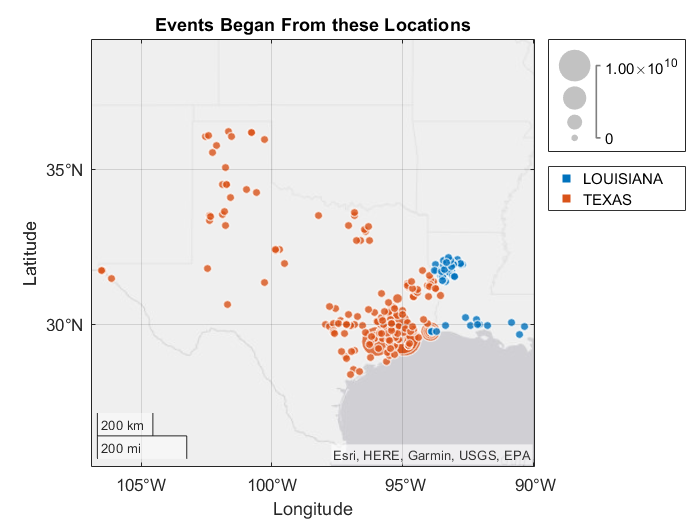

geobubble(harvey_top.Begin_Lat,harvey_top.Begin_Lon,harvey_top.Property_Cost, harvey_top.State)
legend show

title('Events Began From these Locations')

#### End Locations

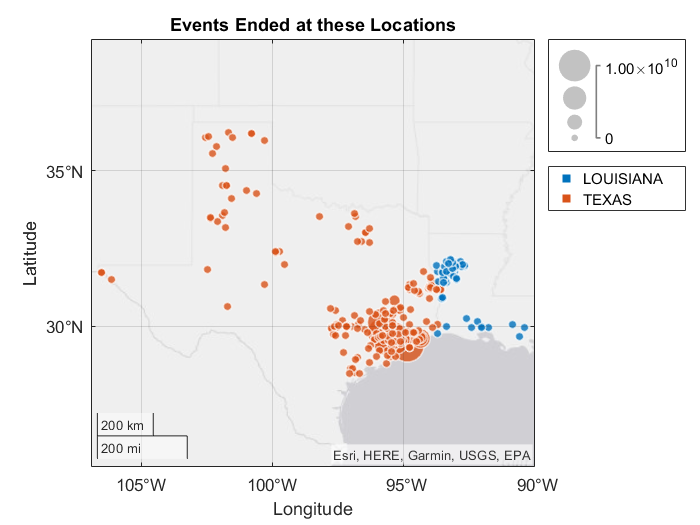

geobubble(harvey_top.End_Lat,harvey_top.End_Lon,harvey_top.Property_Cost, harvey_top.State)
title('Events Ended at these Locations')

## Analysis

### Three Counties with Most Events in Texas

Below are given the** top 3** Counties in **Texas** which encountered the most number of events during Harvey.

state_1 = harvey_top(harvey_top.State == "TEXAS", :);
county_top = groupsummary(state_1, 'CZ_Name');
county_top = sortrows(county_top, 2, 'descend');
county_top = county_top(1:3,1)

county_top = 3×1 table
     CZ_Name 
    _________

    HARRIS   
    GALVESTON
    FORT BEND


### Three Counties with Most Events in Louisiana

Below are given the** top 3** Counties in **Louisiana** which encountered the most number of events during Harvey.

state_2 = harvey_top(harvey_top.State == "LOUISIANA", :);
county_top2 = groupsummary(state_2, 'CZ_Name');
county_top2 = sortrows(county_top2, 2, 'descend');
county_top2 = county_top2(1:3,1)

county_top2 = 3×1 table
      CZ_Name   
    ____________

    NATCHITOCHES
    SABINE      
    RED RIVER   


### Three Counties with Highest Property Cost in Texas

The counties with most property cost in **Texas **are given below.

county1_property = groupsummary(state_1, 'CZ_Name', 'sum', 'Property_Cost');
county1_property = sortrows(county1_property, 3, 'descend');
county1_property = county1_property(1:3,[1,3])

county1_property = 3×2 table
     CZ_Name      sum_Property_Cost
    __________    _________________

    GALVESTON             2e+10    
    FORT BEND        1.6004e+10    
    MONTGOMERY          1.4e+10    


### Three Counties with Highest Property Cost in Louisiana

The counties with most property cost in **Louisiana **are given below.

county2_property = groupsummary(state_2, 'CZ_Name', 'sum', 'Property_Cost');
county2_property = sortrows(county2_property, 3, 'descend');
county2_property = county2_property(1:3,[1,3])

county2_property = 3×2 table
     CZ_Name      sum_Property_Cost
    __________    _________________

    CALCASIEU            6e+07     
    BEAUREGARD         1.5e+07     
    ACADIA               2e+05     


## Conclusions and Recommendations

The Most Affected states were Texas and Louisiana and hence the company should focus on these states firstly to send people to.  However, the property cost to the counties in **Texas** was relatively muh higher than that to the **Louisiana **and can be seen that the property cost of **Calcasieu** of **Louisiana** was lower than **Montgomery** of **Texas, **which means the company should be prioritising Texas over. We may also note that there may be other counties in Texas too which had higher damage than **Calcasieu** of Louisiana which the company should look into too. 

It is also clearly visible from the plots that the events did most dammage at the coastal regions and the most affected areas are not much far from each other.